# Correspondence analysis

#### Background 

Correspondence analysis is a multivariate graphical technique designed to analyze two-way and multi-way tables, containing some measures of the correspondence between the rows and columns. It decomposes the data matrix into a set of singular vectors and singular values, allowing for the visualization of the data in the reduced dimensionality space. The main goal is to reveal the structure of the data in terms of the associations between the row and column categories. The main result is a two-dimensional plot showing the structure of the data. The theory and practice of correspondence analysis are presented in several books by Greenacre,

#### Example 1: the housetasks dataset

The data are a contingency table containing 13 housetasks and their repartition in the couple: rows are the different tasks, colums values are the frequencies of the tasks done: "by the wife only", "alternatively by the husband only" or "jointly",


N=[156	14	2	4;
    124	20	5	4;
    77	11	7	13;
    82	36	15	7;
    53	11	1	57;
    32	24	4	53;
    33	23	9	55;
    12	46	23	15;
    10	51	75	3;
    13	13	21	66;
    8	1	53	77;
    0	3	160	2;
    0	1	6	153];
rowslab={'Laundry' 'Main_meal' 'Dinner' 'Breakfast' 'Tidying' 'Dishes' ...
    'Shopping' 'Official' 'Driving' 'Finances' 'Insurance'...
    'Repairs' 'Holidays'};
colslab={'Wife'	'Alternating'	'Husband'	'Jointly'};


tableN=array2table(N,'VariableNames',colslab,'RowNames',rowslab);
tableN.Properties.DimensionNames=["House Tasks" "Who does it"];

disp(tableN)

                 Wife    Alternating    Husband    Jointly
                 ____    ___________    _______    _______

    Laundry      156         14             2          4  
    Main_meal    124         20             5          4  
    Dinner        77         11             7         13  
    Breakfast     82         36            15          7  
    Tidying       53         11             1         57  
    Dishes        32         24             4         53  
    Shopping      33         23             9         55  
    Official      12         46            23         15  
    Driving       10         51            75          3  
    Finances      13         13            2

As the above contingency table is not very large, with a quick visual examination it can be seen that: 

The house tasks Laundry, Main_Meal and Dinner are dominant in the column Wife.

Repairs are dominant in the column Husband, Holidays are dominant in the column Jointly. 

This information is visualized by the balloonplot function of FSDA.

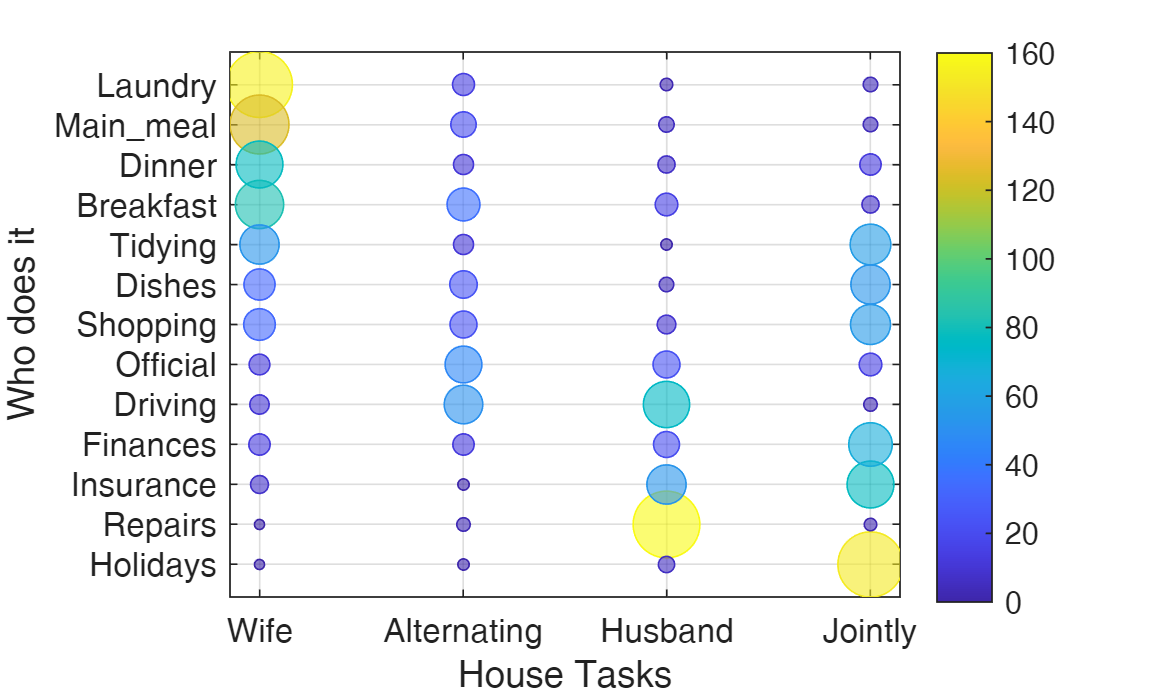

balloonplot(tableN);

Function CorAna of FSDA performs correspondence analysis and provides a graphical summary together with all the information of the importance of the different row and column points.

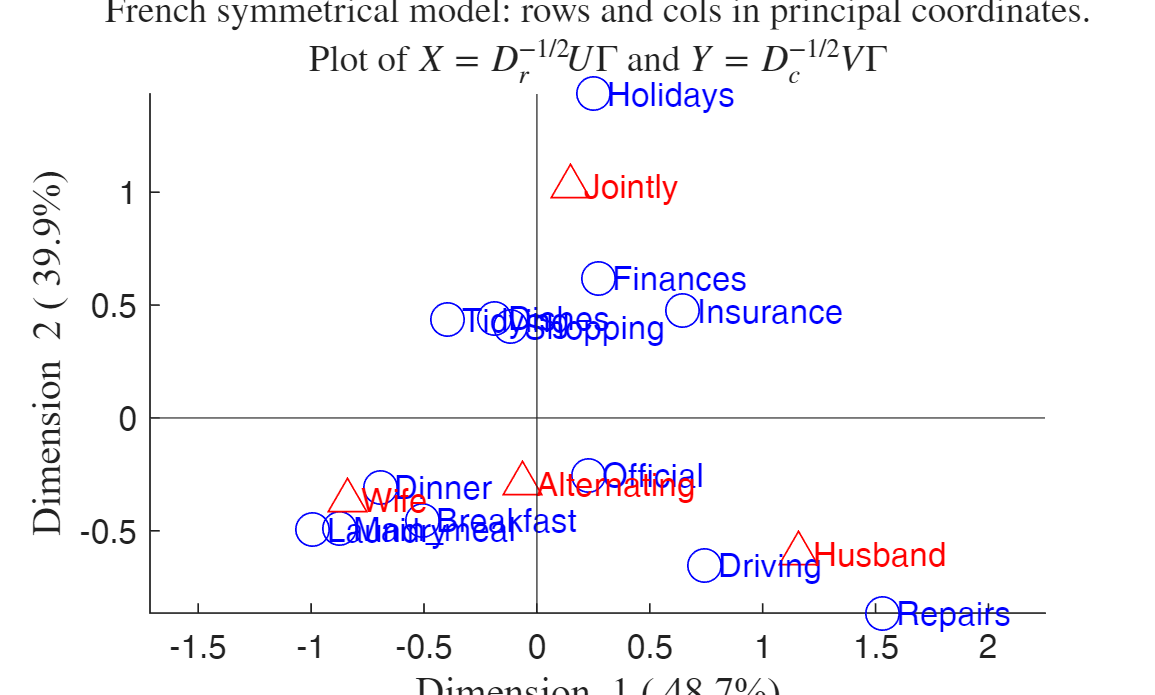

Summary
             Singular_value    Inertia    Accounted_for    Cumulative
             ______________    _______    _____________    __________

    dim_1       0.73681        0.54289       0.48692        0.48692  
    dim_2       0.66709          0.445       0.39913        0.88605  
    dim_3       0.35644        0.12705       0.11395              1  

ROW POINTS
Results for dimension: 1
                  Scores     CntrbPnt2In    CntrbDim2In
                 ________    ___________    ___________

    Laundry      -0.99184       0.18287       0.73999  
    Main_meal    -0.87559       0.12389        0.7416  
    Dinner       -0.69257      0.054714

out=CorAna(tableN);

The circle points represent the house tasks, and the labels represent "who does it". The x-axis and y-axis represent the first and second dimensions of the correspondence analysis, respectively. The plot allows you to visualize the relationships between the house tasks and who does it in the data set.

#### Example 2: the children dataset

The data used here are a contingency table that summarizes the answers given by different categories of people to the following question:

According to you, what are the reasons that can make hesitate a woman or a couple to have children?

The input N is a matrix with 18 rows and 8 columns. Rows represent the the different reasons mentioned, columns represent the different categories (education, age) people belong to.

Active rows (rows 1:14) : Rows that are used during the correspondence analysis.

Supplementary rows (rows 15:18): the coordinates of these rows will   be predicted using the CA informations and parameters obtained with  active rows/columns

Active columns (columns 1:5): columns that are used for the  correspondence analysis.

Supplementary columns (6:8): the coordinates of  these columns will be predicted.

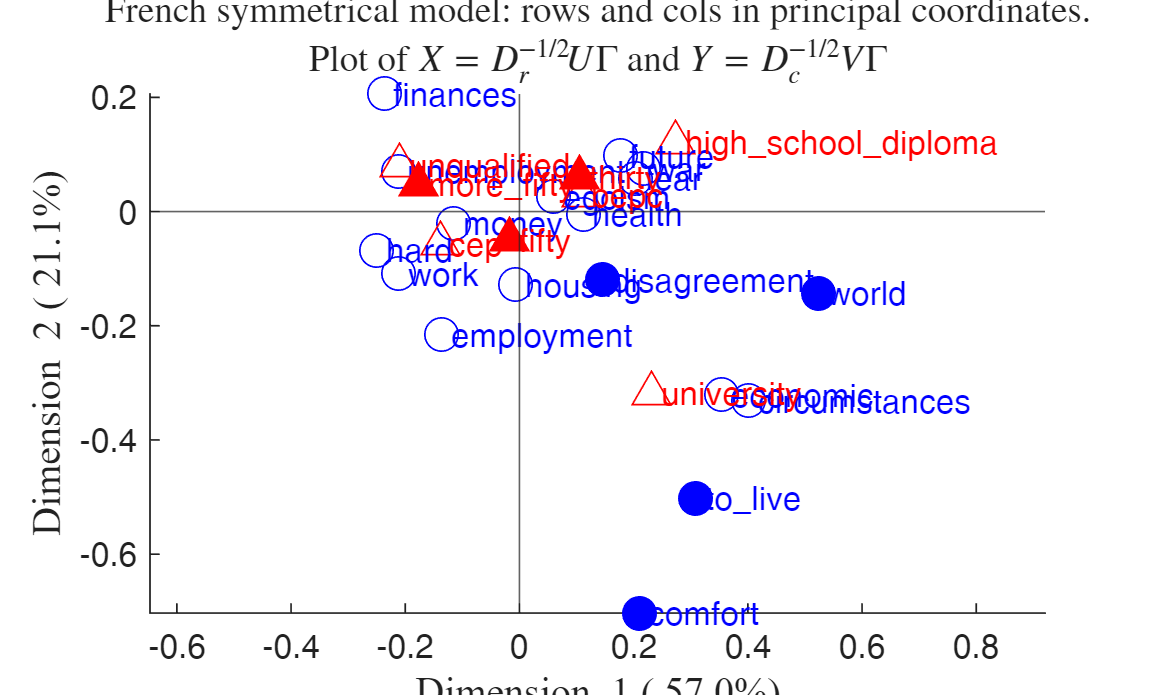

Summary
             Singular_value     Inertia     Accounted_for    Cumulative
             ______________    _________    _____________    __________

    dim_1        0.18815        0.035402       0.57043        0.57043  
    dim_2        0.11452        0.013115       0.21132        0.78175  
    dim_3       0.085447       0.0073011       0.11764        0.89939  
    dim_4       0.079018       0.0062439       0.10061              1  

ROW POINTS
Results for dimension: 1
                      Scores      CntrbPnt2In    CntrbDim2In
                     _________    ___________    ___________

    money             -0.11527      0.045499        0.42845 
    fut

N=[51	64	32	29	17	59	66	70;
    53	90	78	75	22	115	117	86;
    71	111	50	40	11	79	88	177;
    1	7	5	5	4	9	8	5;
    7	11	4	3	2	2	17	18;
    7	13	12	11	11	18	19	17;
    21	37	14	26	9	14	34	61;
    12	35	19	6	7	21	30	28;
    10	7	7	3	1	8	12	8;
    4	7	7	6	2	7	6	13;
    8	22	7	10	5	10	27	17;
    25	45	38	38	13	48	59	52;
    18	27	20	19	9	13	29	53;
    35	61	29	14	12	30	63	58;
    2	4	3	1	4	nan  nan	nan	  ;
    2	8	2	5	2	nan  nan	nan;
    1	5	4	6	3	nan  nan	nan;
    3	3	1	3	4	nan  nan	nan];
% rowslab = cell containing row labels
rowslab={'money','future','unemployment','circumstances',...
    'hard','economic','egoism','employment','finances',...
    'war','housing','fear','health','work','comfort','disagreement',...
    'world','to_live'};
% colslab = cell containing column labels
colslab={'unqualified','cep','bepc','high_school_diploma','university',...
    'thirty','fifty','more_fifty'};

tableN=array2table(N,'VariableNames',colslab,'RowNames',rowslab);
% Extract just active rows
Nactive=tableN(1:14,1:5);

Sup=struct;
Sup.r=N(15:18,1:5);
Sup.c=N(1:14,6:8);
Sup.Lr=rowslab(15:18);
Sup.Lc=colslab(6:8);
% Call to CorAna with supplementary rows and columns
out=CorAna(Nactive,'Sup',Sup);

**Dimension 1 (horizontal axis)**** — *****Socioeconomic vs. Ideological Concerns***

- **On the left (negative side)**:

- **Reasons**: “money”, “unemployment”, “economic”, “housing”, “work”, “future”

- **Groups**: *unqualified*, *cep*, *bepc*, *fifty*, *more_fifty*

- These are **material/structural concerns** and **older or less-educated respondents**.

- Interpretation: These groups are **more likely to cite financial insecurity, job instability, and housing conditions** as reasons for hesitating to have children.

- **On the right (positive side)**:

- **Reasons**: “egoism”, “freedom”, “disagreement”, “comfort”, “to_live”

- **Groups**: *university*, *high_school_diploma*, *thirty*

- These are **individualistic or value-based concerns** expressed more by **younger, more educated people**.

- Interpretation: These respondents emphasize **personal lifestyle, freedom, and ideological reasons** for delaying or avoiding children.

**🔸 ****Dimension 2 (vertical axis)**** — *****Personal vs. Global Concerns***

- **At the top**:

- **Reasons**: “fear”, “health”, “war”, “world”

- These reasons represent **emotional, global, or existential anxieties**.

- May be associated with older individuals (e.g., *more_fifty*) due to increased life experience or pessimism about the future.

- **At the bottom**:

- **Reasons**: “employment”, “housing”, “comfort”, “work”

- These reasons reflect **practical daily-life concerns**.

- Likely tied to working-age groups who are balancing careers and family life.

**🔍 Group-Reason Associations:**

CONCLUSIONS ABOUT TRADITIONAL CORRESPONDENCE ANALYSIS

This Correspondence Analysis reflects **deep social cleavages** in how people perceive the barriers to parenthood:

- **Less-educated and older individuals** emphasize **external/material obstacles** (money, unemployment).

- **Younger, more educated individuals** emphasize **personal/lifestyle considerations** (egoism, comfort, fear of losing freedom).

- **Emotional and existential concerns** (e.g., fear, war, world) are also visible, especially among older respondents.

This mirrors findings in the original *Traitements Statistiques des Enquêtes*, showing how **CA can reveal underlying cultural and ideological structures** in survey data.

#### Example 3: the clothes dataset

Marco Riani, Anthony C. Atkinson, Francesca Torti, Aldo Corbellini, Robust Correspondence Analysis, *Journal of the Royal Statistical Society Series C: Applied Statistics*, Volume 71, Issue 5, November 2022, Pages 1381–1401, [https://doi.org/10.1111/rssc.12580](https://doi.org/10.1111/rssc.12580)

The data are in the context of European Union (EU) international trade, which is regulated in compliance with the World Trade Organization ([1994](about:blank<javascript:;>)), and are available publicly in the COMEXT database of the European statistical office (Eurostat).

The clothes data contains a contingency table between the 28 member states of the European Union (data collected well before Brexit) and 5 price segments. These are occurrences of country trade flows, for a wide set of clothes: x1 denotes the lowest price segment and x5 the highest price segment and In all there are 4373 counts.

load clothes.mat
disp(clothes)

          x1     x2    x3    x4    x5
          ___    __    __    __    __

    GB    134    76    43    50    49
    SK    173    62    20    23    16
    BG     67    76    48    36    23
    IE     11    21    31    36    52
    BE     25    32    57    60    58
    ES     32    42    40    67    67
    PL     20    35    31    41    41
    FI     10    16    23    23    24
    GR     54    28    29    30    23
    HU     12    19    14    15    20
    SI      9    10    14    20    23
    NL     52    43    38    47    54
    IT     21    36    33    30    36
    RO     85    74  

The data considered cover a period of several years, ending in 2017.

disp(clothes.Properties.Description)

The clothes data contains a contingency table between the 28 member states of the European Union (data collected well before Brexit) and 5 price segments. These are occurrences of country trade flows, for a wide set of clothes: x1 denotes the lowest price segment and x5 the highest price segment and In all there are 4373 counts.


The main interest in the analysis is in the row profiles: does the proportion of flows in each price segment vary in any meaningful way between countries? We start by looking at the breakdown of X2 afforded by the Mahalanobis distances which are plotted in the Figure below.

For ease of interpretation we have included an empirical simultaneous confidence band. This was generated under the independence hypothesis of frequencies that depend only on row and column totals, by simulating 10,000 tables using the algorithm of Boyett ([1979](about:blank<javascript:;>)) as modified by Patefield ([1981](about:blank<javascript:;>)) to produce tables with the same row and column totals as the data

The MCD estimates are equal to the classical estimates h=n=4373
Finding empirical bands
Empirical band is very extreme: running 5000 replicates


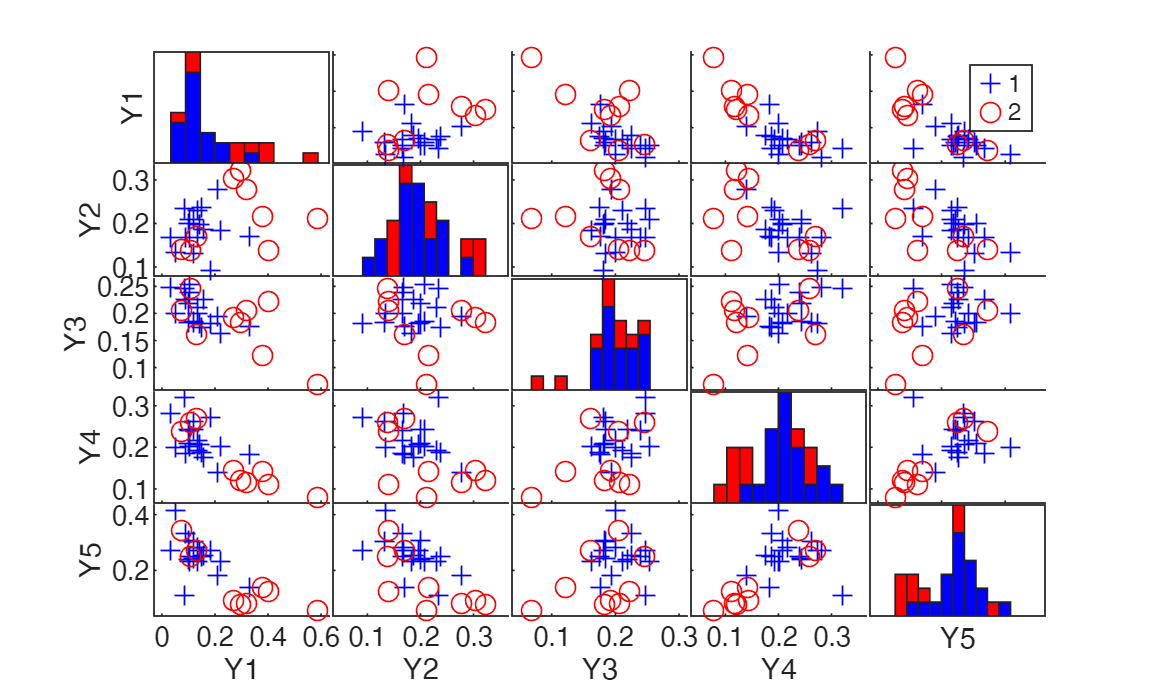

Ntab=clothes;
N=table2array(Ntab);
[I,J]=size(N);
n=sum(sum(N));
r=sum(N,2)/n;
cprime=sum(N,1)/n;

ProfileRows=(N./sum(N,2));
d2=mahalCorAna(ProfileRows,cprime);

[RAW]=mcdCorAna(Ntab,'plots',1,'findEmpiricalEnvelope',true,...
    'conflev',1-0.01/size(N,1),'bdp',n);

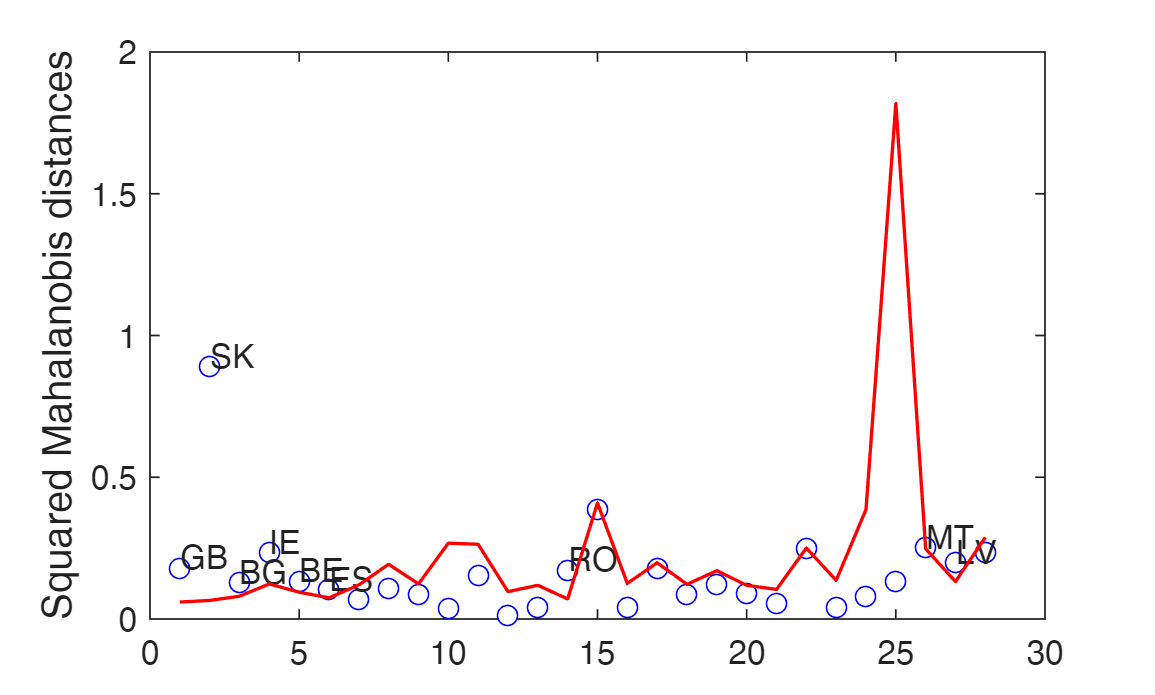

plBIC=findobj('type','figure','Name','Residual plot');
figure(plBIC)
title('')

A Bonferroni approximation was used to find the 99% simultaneous confidence band for the rows of the table. This required the 100(1−0.01/28) = 99.964 percentage point of the empirical distribution for each country. To be conservative we took the 9997th ordered value out of 10,000. The jagged nature of the envelope is caused by the varying row masses—in particular the largest spike is for unit 25, LU, for which $f_i.$ is only 0.0025.

The plot below shows the distance weighted by the row masses $f_i.$⁠, with the appropriately weighted envelope. The seven largest distances correspond to SK, GB, RO, IE, BG, LV and ES, all lying well outside the envelope. AT, which appears as relatively extreme in the unweighted plot appears much less extreme in the weighted plot. Again it is a country with low mass; $f_i.$= 0.0137.

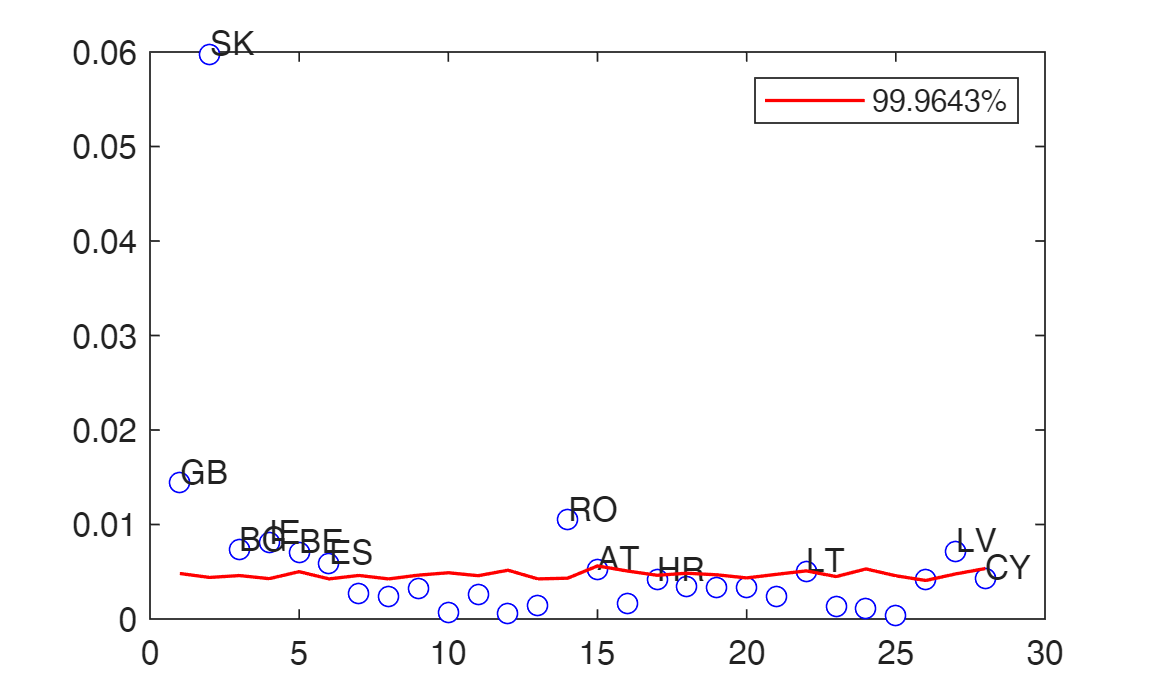

labelsr=Ntab.Properties.RowNames;
malindexplot(RAW.md.*r,RAW.EmpEnv.*r,'label',labelsr,'numlab',{12});
hh= findobj('Color','r');
legend(hh(1),'99.9643%')
title('')

if prin==1
    % print to postscript
    print -depsc figs\MHD1right.eps;
end

We now turn to the correspondence analysis of these data. This should provide information not only on the relationship between the row profiles, but also their relationship to the five ordered price categories. The plot of the correspondence analysis is in Figure below, with the countries represented by circles. This is not of the standard structure seen in such plots as Exhibits 9.2 and 10.2 of Greenacre ([2017](about:blank<javascript:;>)) in which the two axes intersect near the centre of a point cloud of the projections of row profiles. Here, on the other hand, the intersection of the axes leaves a cloud of points to its right, with a straggle of points to the left of the intersection. In order, the most remote on the first axis, which accounts for 83.3% of the total variability, are SK, MT, GB, RO, LV, BG and GR. Five of these are indicated as outlying by the plots of Mahalanobis distances in Figure [1](about:blank<javascript:;>). In addition, the order is changed and AT now appears as a member of the central group. 

out=CorAna(Ntab,'plots',0);

Summary
             Singular_value     Inertia     Accounted_for    Cumulative
             ______________    _________    _____________    __________

    dim_1        0.38033         0.14465       0.83291        0.83291  
    dim_2        0.13623        0.018557       0.10686        0.93976  
    dim_3       0.079538       0.0063262      0.036427        0.97619  
    dim_4       0.064303       0.0041349      0.023809              1  

ROW POINTS
Results for dimension: 1
           Scores      CntrbPnt2In    CntrbDim2In
          _________    ___________    ___________

    GB     -0.41105      0.094025       0.94458  
    SK     -0.92168       0.394

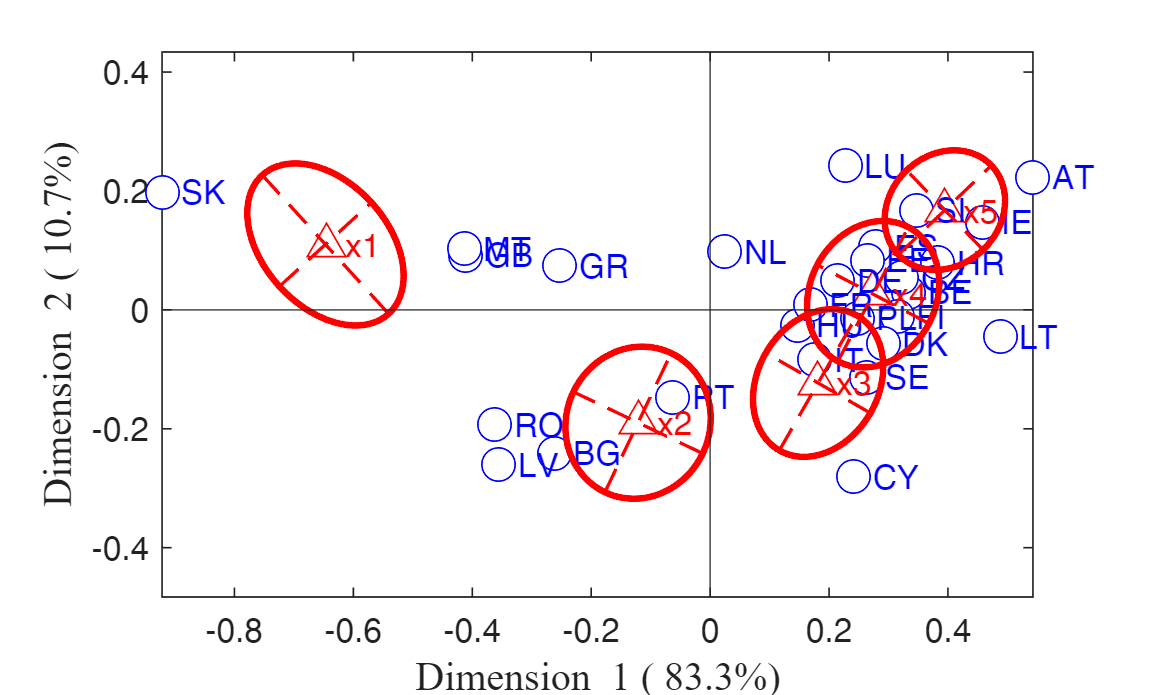

confellipse=struct;
confellipse.conflev=0.999;
confellipse.selCols=1:5;
confellipse.selRows='';
confellipse.method={'multinomial'}; %'bootRows' 'bootCols'};
CorAnaplot(out,'changedimsign',[false false],'confellipse',confellipse)
legend('off')
box('on')
title('')

**ROBUST CORRESPONDENCE ANALYSIS**

We now report the results of the MCD analysis of the clothes data with maximal breakdown point of 50%, that is *h* = 2189. We first establish the outliers and then describe the results of the correspondence analysis with the outlying rows deleted.

Figure below shows the plot of the robust Mahalanobis distances by country. This is the robust version of the lower panel of previous Figures. Not only is the simultaneous envelope of course the same in the two figures, but there are again seven outliers. AT is no longer marginally outlying, but PT is very close to the envelope.

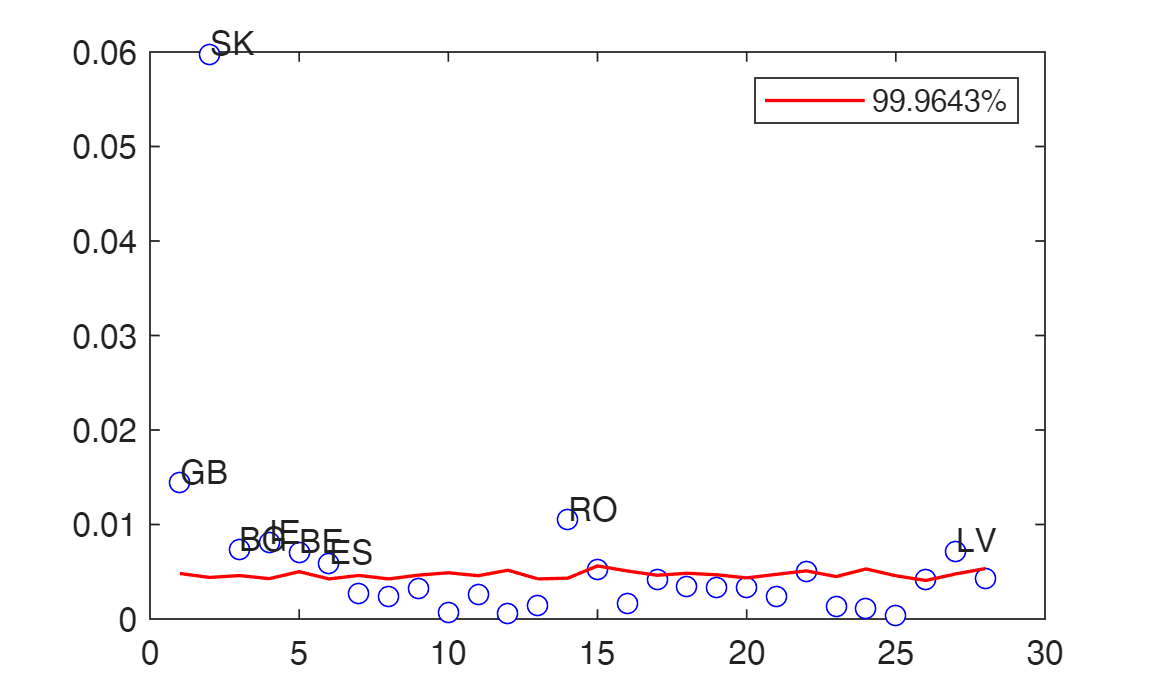

%% Figure 3 top
rawmd=RAW.md.*r;
malindexplot(rawmd,RAW.EmpEnv.*r,'label',labelsr,'numlab',{8});

% findobj(gca,'line',{'Displayname'})
hh= findobj('Color','r');
legend(hh(1),'99.9643%')
title('')

To continue our analysis of the data we give, in Figure below, the plot from the correspondence analysis of the data when the seven outlying rows are excluded from estimation of the principal coordinates. They are, however, plotted in the figure, and so have become ‘supplementary points’. The points of the remaining 21 observations now form a scatter around the intersection of the axes: there are 16 countries forming a relatively tight cluster with five countries scattered slightly more remotely around them. There is then, at lower values of the first principal axis, a seeming cluster of six countries. The most remote country on this axis is Slovakia. The ordering along this axis seems to reflect an increasing proportion of purchases of the cheapest clothes. The second lowest point on this axis is that for GB. The other five outliers are for countries with much smaller economies; the other major economies of Europe at that time (FR, IT, DE, PL and ES) all have values for the first axis close to zero; that is, they are typical European countries.

%% Figure 4: robust correspondence analysis
selsup={'GB', 'SK' 'MT' 'GR' 'RO', 'LV', 'BG'};
selactive=setdiff(Ntab.Properties.RowNames,selsup);
Nsupr=Ntab(selsup,:);
Nactive=Ntab(selactive,:);
Sup=struct;
Sup.r=Nsupr;
out=CorAna(Nactive,'Sup',Sup,'plots',0);

Summary
             Singular_value     Inertia     Accounted_for    Cumulative
             ______________    _________    _____________    __________

    dim_1        0.15672        0.024561       0.55645        0.55645  
    dim_2        0.10187        0.010377       0.23509        0.79153  
    dim_3       0.078303       0.0061314       0.13891        0.93045  
    dim_4       0.055408       0.0030701      0.069555              1  

ROW POINTS
Results for dimension: 1
            Scores      CntrbPnt2In    CntrbDim2In
          __________    ___________    ___________

    AT      -0.31495      0.086053        0.61367 
    BE      -0.11623      0.

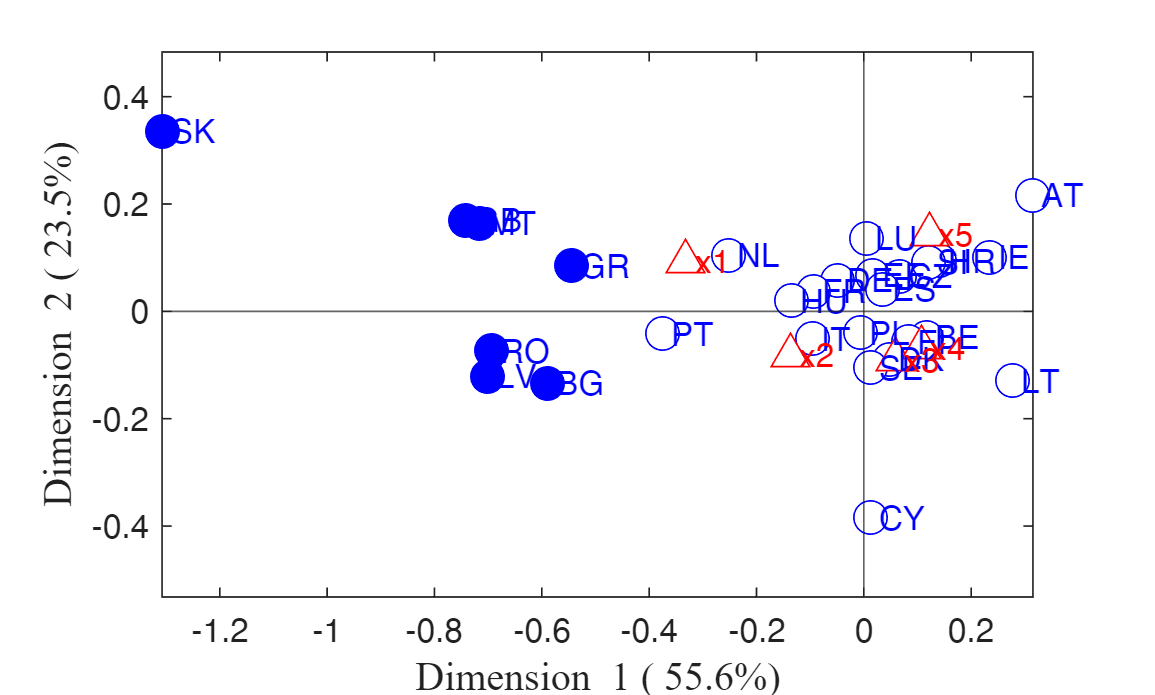


CorAnaplot(out,'changedimsign',[true false])
box('on')
title('')

The Figure below repeats the previous Figure, but the focus is now on the columns. As previously, we give the confidence regions for the five column points. Removing the seven outliers from estimation causes a sharp change in the assessment of the significance of columns points. Now the regions for the three central price categories, x2-x4⁠, overlap with the origin. After removal of the outliers the information on the effect of price comes only from the two most extreme categories. While in the non-robust representation the confidence ellipses for x1 and x2 are very far from those of the other three points, in the robust representation there is considerable overlap in the ellipses for each consecutive pair of price levels.

The first latent dimension can be interpreted as price level; when the outliers are removed, the projection on this dimension of the seven outliers gives values that are much lower than the projection of the column point x1⁠. The second latent dimension now more sharply contrasts the extreme prices (⁠x1 and x5⁠) with the intermediate prices. In the robust correspondence analysis plot, only the column points x1 and x5 show positive values for this latent component. It is also interesting to note that, while in the original representation the countries RO, LV and BG seem to be very close to x2⁠, in the robust representation they are all well to its left.

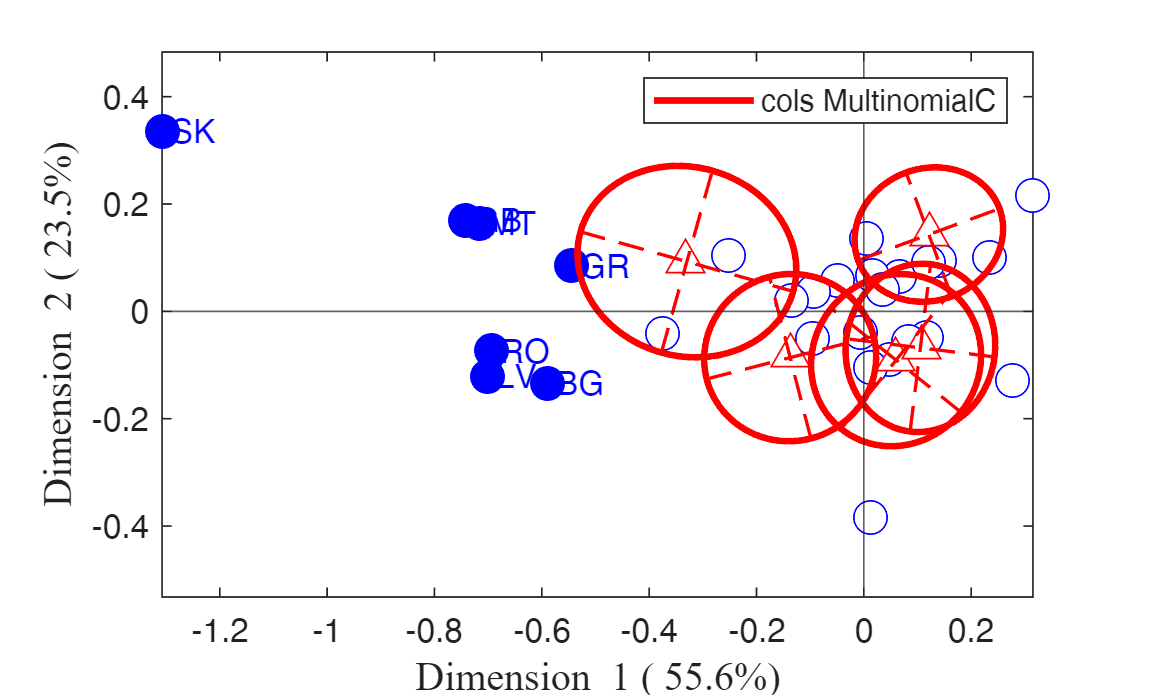

%% Figure 4: Correspondence analysis plot from MCD analysis.
[~,indexesI]=intersect(Ntab.Properties.RowNames,selsup);
confellipse=struct;
confellipse.conflev=0.999;
confellipse.selCols=1:5;
confellipse.selRows='';
confellipse.method={'multinomial'}; %'bootRows' 'bootCols'};
plots=struct;
plots.FontSize=0.01;
CorAnaplot(out,'changedimsign',[true false],'confellipse',confellipse,...
    'plots',plots)
box('on')
title('')

The robust analysis leads also to the revelation of further information in the data. For example, Figure below is a scatterplot matrix of the row profiles with the outliers highlighted. On the diagonals we give the box plots for the five values of *x* separated into normal and outlying rows. The structure is abundantly clear. The first row shows the high values of x1 for all seven outlying countries, whereas the values of x4 and x5 in the last two rows are almost all lower for the outliers than for the normal countries. A panel such as that for x1 and x5 shows complete separation of the two groups.

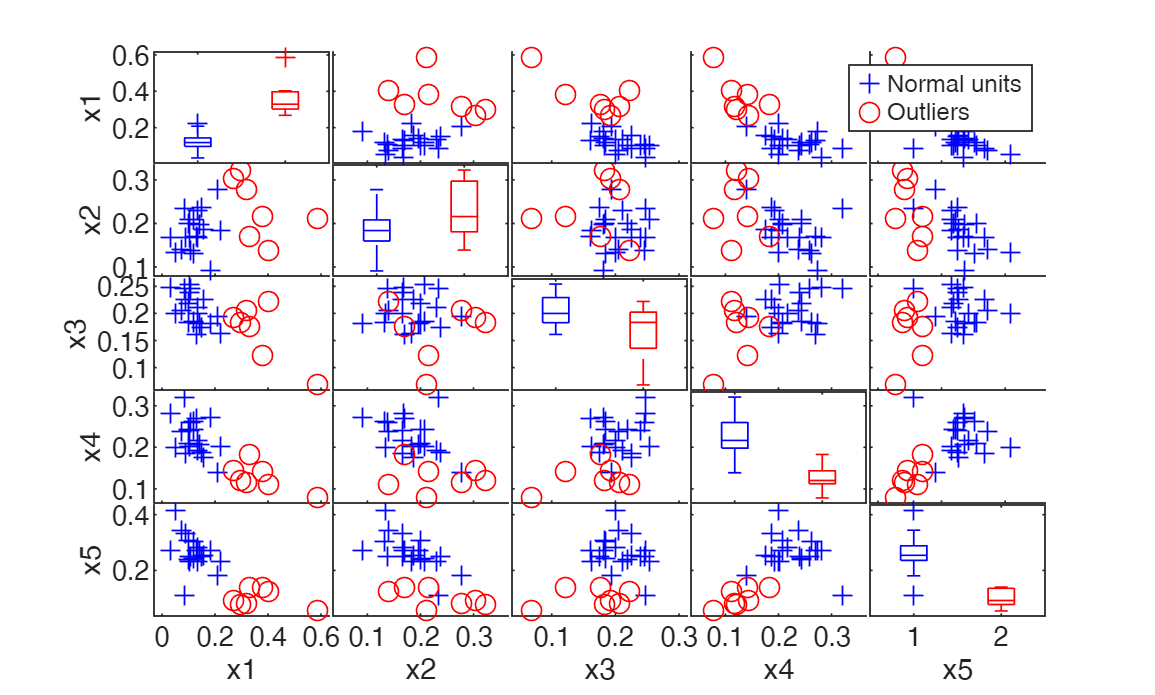

%% Figure 5: Scatter plot matrix of row profiles with outliers
selsup={'GB', 'SK' 'MT' 'GR' 'RO', 'LV', 'BG'};
group=ones(I,1);
label=Ntab.Properties.RowNames;
[~,indeOut]=intersect(label,selsup);
group(indeOut)=2;
ProfileRowsTable=array2table(ProfileRows,'RowNames',label,'VariableNames',Ntab.Properties.VariableNames);
[H,AX,BigAx]=spmplot(ProfileRowsTable,'group',group,'dispopt','box');
aa={'Normal units' 'Outliers'};
% findobj('legend','off')
add2spm(H,AX,BigAx,'userleg',aa)

List of the main FSDA functions which have been used 

#### Main references

Traitements Statistiques des Enquetes (D. Grange, L. Lebart, eds.) Dunod, 1993

Kroonenberg, P. M. and Lombardo, R. (1999) Nonsymmetric correspondence analysis: a tool for analysing contingency tables with a dependence structure. *Multivariate Behavioral Research*, **34**, 367–396

Riani, M. Atkinson, A. C.,  Torti F. and Corbellini A. (2022), Robust Correspondence Analysis, *Journal of the Royal Statistical Society Series C: Applied Statistics*, Volume 71, Issue 5, Pages 1381–1401, [https://doi.org/10.1111/rssc.12580](https://doi.org/10.1111/rssc.12580)